# **2D-Rigid Body Ballistic Pose Estimation with IMU** 

**สมาชิก** 

- ธนชาติ เสถียรจารุการ 	รหัสนักศึกษา 63340500021 

- พชรพล เพชรรัตน์ 	        รหัสนักศึกษา 63340500036 

- ลัทธวัฒน์ เลาหะพันธุ์ 	รหัสนักศึกษา 63340500056 

- วรนิษฐา ลาภเกียรติถาวร 	รหัสนักศึกษา 63340500057 

*System Description (Physical Characteristics, and Mathematics Model)*

*    o Overall*

*    o Mechanical Plant*

*    o Sensors & Actuators*

*Methodology*

*    o Prediction Model & Estimation Method*

*Implementation*

*    o State Machine Diagram of the experiment*

*Results*

*    o Comparison w/ ground truth**

*Discussion*

*    o Any findings or insights from the experiment*

**System Description **(Physical Characteristics and Mathematics Model)

        ระบบนี้เป็นระบบคาดคะเนตำแหน่งและทิศทางการหมุนของวัตถุที่มีรูปร่างเป็นสี่เหลี่ยมผืนผ้าขนาด $6\pm 0\ldotp 1\;\textrm{cm}\times 12\pm 0\ldotp 1\;\textrm{cm}\times 1\pm 0\ldotp 05\;\textrm{cm}$ มีมวล $0\ldotp 1915\;\textrm{kg}$ inertia $0\ldotp 00029268\;\textrm{kg}\cdot \;m^2$ และมีความหนาแน่น $2710\pm 10\;\textrm{kg}/m^3$ ซึ่งถูกโยนเเละมีการเคลื่อนที่เป็นวิถีโค้งในระนาบสองมิติหรือระนาบ XY และหมุนรอบแกน Z ทำให้วัตถุมีทั้งการเคลื่อนที่เชิงมุมและการเคลื่อนที่เชิงเส้นภายใต้แรงโน้มถ่วงของโลก ในการประมาณตำแหน่งและทิศทางการหมุนของวัตถุนี้สามารถทำได้โดยการใช้ Gyroscope และ Accelerometer ซึ่งอยู่ใน IMU ที่ติดตรึงเเน่นกับวัตถุ โดยมีระยะและมุมของ IMU ที่ติดบนวัตถุดังนี้

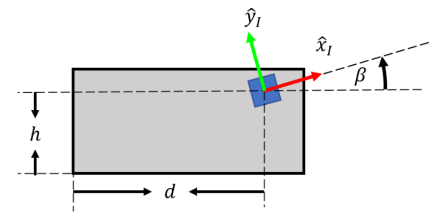

ซึ่งวัตถุมีตำแหน่งเริ่มต้นในการโยนคือ $\left\lbrack x_0 \;y_0 \right\rbrack =\left\lbrack 0\pm 0\ldotp 01\;0\pm 0\ldotp 01\right\rbrack \;m$ และมีทิศทางการหมุนเริ่มต้นในการโยนคือ $\theta {\;}_0 =\left\lbrack \frac{\pi }{6}\pm \frac{\pi }{90}\right\rbrack \;\textrm{rad}$ รวมถึงระบบนี้มีการใช้ Kalman Filter เพื่อประมาณค่าตำแหน่งและทิศทางการหมุนให้มีความใกล้เคียงกับความเป็นจริงมากที่สุด โดยระบบสามารถแบ่งได้เป็น 2 ส่วนดังนี้

1. Simulator เป็นส่วนที่จำลอง plant ของระบบ โดยในระบบนี้ plant คือการเคลื่อนที่แบบโปรเจคโทล์ของวัตถุบน XY plane เเละวัตถุมีการหมุนรอบเเกน Z ซึ่ง plant จะถูกจำลองออกมาในรูปแบบ continuous-time

    ซึ่งเราสามารถจำลองการเคลื่อนที่ของวัตถุและค่าที่ IMU อ่านได้ ผ่านการเขียนสมการความสัมพัทธ์ทางคณิตศาสตร์ระหว่างความเร่ง ความเร็ว และระยะกระจัดทั้งการเคลื่อนที่เชิงเส้นและเชิงมุมได้ดังนี้ี้

    1.1 การเคลื่อนที่แบบเชิงมุม

            เนื่องจากวัตถุเคลื่อนที่โดยไม่มีแรงภายนอกมากระทำทำให้ $\tau \;=0$ และ$M=0$ ดังนั้น


$$\alpha =0$$


แต่ความไม่แน่นอนจากแรงภายนอกทำให้ $\alpha \not= 0$ ดังนั้นเราจึงกำหนดให้ noise ของระบบมีค่าเท่ากับ $\alpha$

            จาก $\omega =\int_{\tau =0}^t \alpha \;\;d\tau \;$จะได้


$$\omega \;\left(t\right)={\omega \;}_0 +\alpha \;\cdot t$$


            จาก $\theta \;=\int_{\tau =0}^t \omega \;\;d\tau \;$จะได้


$$\theta \;\left(t\right)={\omega \;}_0 \cdot \;t+\frac{1}{2}\cdot \;\alpha \;\cdot tˆ^2$$


            โดยค่า $\omega$ ที่ได้จะนำไปใช้เป็นค่าที่ Gyroscope อ่านได้จาก plant เเต่เนื่องจาก Gyroscope ของ IMU ตัวนี้มี measurement noise เป็น gaussian distribution ที่มี variance เท่ากับ 0.01 เราจึง บวกค่า noise ก่อนที่จะนำค่า Gyroscope เข้า Kalman filter สำหรับการประมาณค่า $\theta \;\;\dot{\theta} \;\mathrm{เเละ}\;\ddot{\theta}$ 

    1.2 การเคลื่อนที่แบบเชิงเส้น ทั้งแกน x และแกน y

            เนื่องจากวัตถุเคลื่อนที่ภายใต้แรงโน้มถ่วงของโลกโดยไม่มีแรงกระทำจะได ้


$$\overset{\rightharpoonup }{a} ={\left[\begin{array}{c}
0\\
-g
\end{array}\right]}$$
 

            โดย $g\simeq 9\ldotp 81\;m/s^2$

            จาก $\overset{\rightharpoonup }{v} =\int_{\tau =0}^t \overset{\rightharpoonup }{a} \;d\tau \;$จะได้


$$\overset{\rightharpoonup }{v\left(t\right)} =\overset{\rightharpoonup }{v_0 } +\overset{\rightharpoonup }{a} \cdot t$$


            จาก $\overset{\rightharpoonup }{p} =\int_{\tau =0}^t \overset{\rightharpoonup }{v} \;d\tau$ จะได้


$$\overset{\rightharpoonup }{p\left(t\right)} =\overset{\rightharpoonup }{v_0 } \cdot \;t+\frac{1}{2}\cdot \overset{\rightharpoonup }{a} \cdot t^2$$


        เนื่องจากผู้จัดทำจำลองระบบให้ไม่มีเเรงภายนอกมากระทำกับระบบเลย ซึ่งทำให้ระบบมี $\tau \;\left(\textrm{torque}\right)\;=0$ และ$M\;\left(\textrm{moment}\right)=0$ ดังนั้น $\alpha \;\left(\mathrm{angular}\;\mathrm{acceleration}\right)=0$ หมายความว่าในทุก ๆ จุดของวัตถุจะมีความเร่งเท่ากัน ด้วยเหตุนี้เราจึง model ให้ความเร่งที่ IMU มีค่าเท่ากับความเร่งที่จุด CM ของวัตถุซึ่งก็คือ $\overset{\rightharpoonup }{a} ={\left[\begin{array}{c}
0\\
-g
\end{array}\right]}$เเต่เนื่องจากในความเป็นจริงเเล้วระบบจะมีความไม่เเน่นอนเกิดขึ้นด้วยดังนั้นผู้จัดทำจึง model ให้ความเร่งในเเนว cartesian มีค่าดังนี้ $\overset{\rightharpoonup }{a} ={\left[\begin{array}{c}
0\\
-g
\end{array}\right]}+\overset{\rightharpoonup }{n_a }$ เมื่อกำหนดค่าความเร่งในเเนวเเกน global เรียบร้อยเเล้ว จากนั้นก็คูณ Rotation Matrix ให้กลายเป็นค่าความเร่งที่อยู่ในเเกนของ IMU โดยค่าที่ได้มาจะนำไปใช้เป็นค่าที่ Accelerometer อ่านค่าได้จาก plant เเต่ Accelerometer บน IMU ตัวนี้มี measurement noise เป็น gaussian distribution ที่มี variance เท่ากับ 0.01 เราจึง บวกค่า noise ก่อนที่จะนำค่า Accelerometer เข้า Kalman filter สำหรับการประมาณค่า $\overset{\rightharpoonup }{P} \;\;\overset{\dot{\rightharpoonup} }{P} \;\mathrm{เเละ}\;\overset{\ddot{\rightharpoonup} }{P}$ 

2. State Estimator เป็นการนำค่าที่ได้จากเซนเซอร์ IMU ในส่วน simulator มาประมาณตำแหน่งและทิศทางการหมุนของวัตถุ โดยแบ่งการประมาณเป็น 2 ส่วนคือการเคลื่อนที่เชิงมุมและการเคลื่อนที่เชิงเส้น ซึ่งประมาณโดยการนำค่าที่ได้จากเซนเซอร์เข้า Kalman filter ที่ทำการใส่ค่าตัวแปรจาก state equation และ output equation ที่หาได้ ทำให้ได้ตำแหน่งและทิศทางการหมุนของวัตถุที่ต้องการและเป็นค่าที่มีการประมาณให้ใกลเคียงความเป็นจริง โดยส่วนนี้จะถูกคำนวณในรูปแบบ discrete-time

**Methodology**

        ระบบนี้มีการประมาณโดยใช้ Kalman filter ซึ่งระบบนี้ใช้ Kalman filter ทั้งหมด 2 ตัว สามารถแบ่งได้ดังนี้

1. การเคลื่อนที่เชิงมุม

    เป็นการใช้ Kalman filter และค่าจาก Gyroscope เพื่อประมาณทิศทางการหมุนของวัตถุ การประมาณในส่วนนี้ประกอบด้วย 3 states คือระยะกระจัดการหมุนของวัตถุ ($\theta$) ความเร็วเชิงมุม ($\overset{\cdot }{\theta}$) และความเร่งเชิงมุม ($\overset{\cdot \cdot }{\theta}$) โดย output คือความเร็วเชิงมุมของวัตถุ ซึ่งสามารถเขียนสมการ state และสมการ output ได้ดังนี้


$${\left[\begin{array}{c}
\theta {\left[k+1\right]}\\
\overset{\cdot }{\theta} {\left[k+1\right]}\\
\overset{\cdot \cdot }{\theta} {\left[k+1\right]}
\end{array}\right]}={\left[\begin{array}{ccc}
1 & \Delta t & \frac{1}{2}\Delta t^2 \\
0 & 1 & \Delta t\\
0 & 0 & 1
\end{array}\right]}\cdot {\left[\begin{array}{c}
\theta {\left[k\right]}\\
\overset{\cdot }{\theta} {\left[k\right]}\\
\overset{\cdot \cdot }{\theta} {\left[k\right]}
\end{array}\right]}+{\left[\begin{array}{c}
\frac{1}{6}\Delta t^3 \\
\frac{1}{2}\Delta t^2 \\
\Delta t
\end{array}\right]}\cdot w_{\theta \;}$$



$$y_g =\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack \cdot {\left[\begin{array}{c}
\theta {\left[k\right]}\\
\overset{\cdot }{\theta} {\left[k\right]}\\
\overset{\cdot \cdot }{\theta} {\left[k\right]}
\end{array}\right]}+n_g$$


จากสมการ state และสมการ output จะสังเกตเห็นว่าเป็นสมการ linear ทำให้สามารถจัดรูปให้อยู่ในรูปแบบเมทริกซ์ได้ดังนี้$A={\left[\begin{array}{ccc}
1 & \Delta t & \frac{1}{2}\Delta t^2 \\
0 & 1 & \Delta t\\
0 & 0 & 1
\end{array}\right]}$, $C=\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack$, $G={\left[\begin{array}{c}
\frac{1}{6}\Delta t^3 \\
\frac{1}{2}\Delta t^2 \\
\Delta t
\end{array}\right]}$ซึ่งเมทริกซ์เหล่านี้เป็นเมทริกซ์ที่จะนำไปใส่ใน block ของ Kalman filter เพื่อที่จะนำไปประมาณ state ของระบบส่วนการเคลื่อนที่เชิงมุม

2. การเคลื่อนที่เชิงเส้น

    เป็นการใช้ Kalman filter และค่าจาก Accelerometer เพื่อประมาณตำแหน่งของวัตถุ การประมาณในส่วนนี้ประกอบด้วย 3 states คือตำแน่งของวัตถุ ($\overset{\rightharpoonup }{p}$) ความเร็วเชิงเส้น ($\overset{\cdot }{\overset{\rightharpoonup }{p} }$) และความเร่งเชิงเส้น ($\overset{\cdot \cdot }{\overset{\rightharpoonup }{p} }$) โดยมี known input คือ ความเร่งเนื่องจากแรงโน้มถ่วงของโลก ${\left[\begin{array}{c}
0\\
-g
\end{array}\right]}$และ output คือความเร่งเชิงเส้นของ Accelerometer ซึ่งสามารถเขียนสมการ state และสมการ output ได้ดังนี้


$${\left[\begin{array}{c}
\overset{\rightharpoonup }{p} {\left[k+1\right]}\\
\overset{\cdot }{\overset{\rightharpoonup }{p} } {\left[k+1\right]}\\
\overset{\cdot \cdot }{\overset{\rightharpoonup }{p} } {\left[k+1\right]}
\end{array}\right]}={\left[\begin{array}{ccc}
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & \Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}\\
{\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}\\
{\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}
\end{array}\right]}\cdot {\left[\begin{array}{c}
\overset{\rightharpoonup }{p} {\left[k\right]}\\
\overset{\cdot }{\overset{\rightharpoonup }{p} } {\left[k\right]}\\
\overset{\cdot \cdot }{\overset{\rightharpoonup }{p} } {\left[+1\right]}
\end{array}\right]}+{\left[\begin{array}{c}
\frac{1}{2}\Delta t^2 \cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
\Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}
\end{array}\right]}\cdot {\left[\begin{array}{c}
0\\
-g
\end{array}\right]}+{\left[\begin{array}{c}
\frac{1}{2}\Delta t^2 \cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
\Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}
\end{array}\right]}\cdot w_a$$


$\overset{\rightharpoonup }{y_a } =R_O^I \left(\theta +\beta \;\right)\cdot \left({\overset{\rightharpoonup }{a} }_{O,I}^I -{\left[\begin{array}{c}
0\\
-g
\end{array}\right]}\right)$+$\overset{\rightharpoonup }{n_a }$

จากสมการ state และสมการ output จะได้ว่า $A={\left[\begin{array}{ccc}
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & \Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}\\
{\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}\\
{\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]} & {\left[\begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right]}
\end{array}\right]}$, $B={\left[\begin{array}{c}
\frac{1}{2}\Delta t^2 \cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
\Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}
\end{array}\right]}$, $C=$, $D=$, $G={\left[\begin{array}{c}
\frac{1}{2}\Delta t^2 \cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
\Delta t\cdot {\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}\\
{\left[\begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right]}
\end{array}\right]}$ ซึ่งเมทริกซ์เหล่านี้เป็นเมทริกซ์ที่จะนำไปใส่ใน block ของ Kalman filter เพื่อที่จะนำไปประมาณ state ของระบบส่วนการเคลื่อนที่เชิงเส้น 

**Implementation**

        จากการออกแบบระบบทางกายภาพและการประมาณค่าโดยใช้ Kalman filter ทำให้เห็นว่าระบบประกอบไปด้วย 2 ส่วนหลัก ๆ คือ simulator และ state estimator โดยส่วน simulator จะเป็น plant ของระบบที่มีเซนเซอร์ IMU อยู่ด้วย ในส่วนนี้จะมีการเพิ่ม process noise ซึ่งเป็นความไม่แน่นอนที่สามารถเกิดขึ้นได้บน plant (noise จากแรงภายนอกอื่น ๆ) และ measurement noise ซึ่งเป็นความไม่แน่นอนของเซนเซอร์ที่ใช้ เพื่อให้ระบบใกล้เคียงความเป็นจริงมากขึ้น และในส่วน state estimator จะใช้ Kalman filter ทั้งหมด 2 ตัว สำหรับการเคลื่อนที่เชิงมุมและการเคลื่อนที่เชิงเส้น โดยสาเหตที่ต้องเเยก kalman filter เป็น 2 ส่วนเนื่องจากถ้ารวมเป็นส่วนเดียวจะทำให้ sensor model ของ accelerometer ที่มี Rotation matrix มาเกี่ยวข้องเป็นกลายเป็น non-linear เพราะว่า theta ที่ต้องใช้เเละความเร่งของ CM เป็น State ทั้งคู่ จากข้อมูลข้างต้นทั้งหมดทำให้สามารถเขียน State Machine Diagram ของระบบได้ดังนี้

**Results**

จากการทดสอบระบลทางกายภาพและการประมาณค่าโดยใช้ Kalman filter ทำให้ได้ผลลัพธ์ดังนี้

1. การเคลื่อนที่เชิงมุม

    ในส่วนการเคลื่อนที่เชิงมุม สิ่งที่เราต้องการคือทิศทางการหมุนของวัตถุ ($\theta$) ซึ่งเราสามารถเปรียบเทียบตำแหน่งของวัตถุที่เกิดขึ้นจริงกับตำแหน่งของวัตถุที่ประมาณโดยใช้ Kalman filter ได้ดังนี้

    กราฟที่ 1.1 ทิศทางการหมุนของวัตถุที่เกิดขึ้นจริง

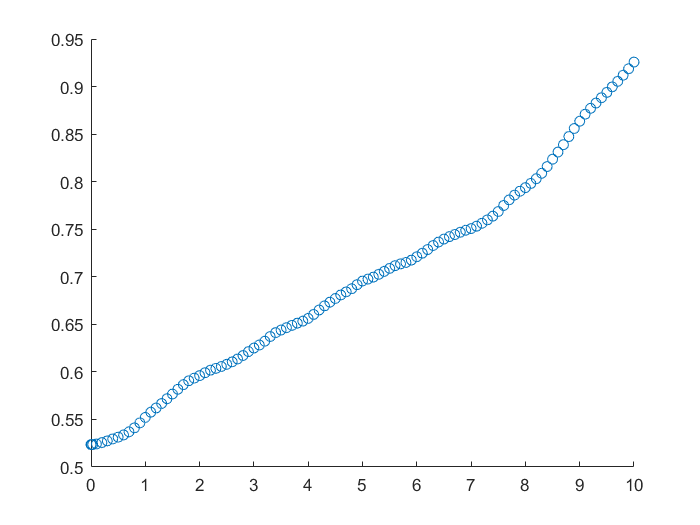

clf
ax = axes;
scatter(ax,ans.theta_t.time,ans.theta_t.data)

    กราฟที่ 1.2 ทิศทางการหมุนของวัตถุที่ประมาณโดยใช้ Kalman filter

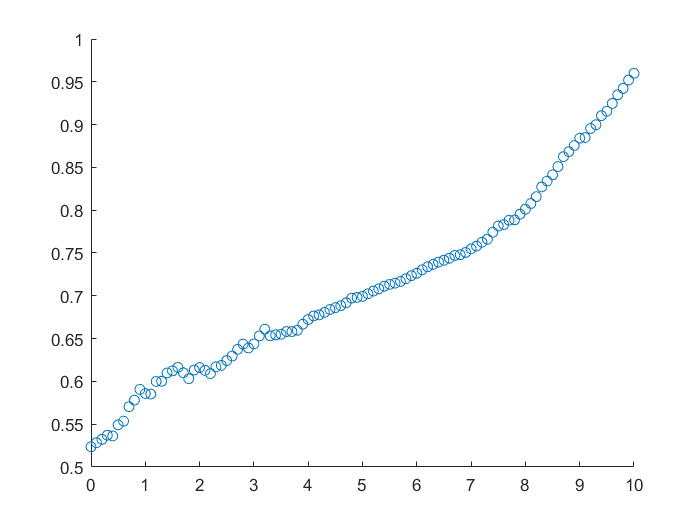

scatter(ax,ans.theta_e.time,ans.theta_e.data)

    จากกราฟที่ 1.1 และ 1.2 ทำให้เห็นว่าทิศทางการหมุนของวัตถุที่เกิดขึ้นจริงกับทิศทางการหมุนของวัตถุที่ประมาณจาก Kalman filter มีความใกล้เคียงกัน โดยมีความไม่แน่นอนของการประมาณทิศทางการหมุนในส่วน state estimation โดยใช้ Kalman filter ดังนี้

% scatter()

2. การเคลื่อนที่เชิงเส้น

    ในส่วนการเคลื่อนที่เชิงเส้น สิ่งที่เราต้องการคือตำแหน่งของวัตถุ ($\overset{\rightharpoonup }{p}$) ซึ่งเราสามารถเปรียบเทียบตำแหน่งของวัตถุที่เกิดขึ้นจริงกับตำแหน่งของวัตถุที่ประมาณโดยใช้ Kalman filter ได้ดังนี้

    กราฟที่ 2.1 ตำแหน่งของวัตถุที่เกิดขึ้นจริง

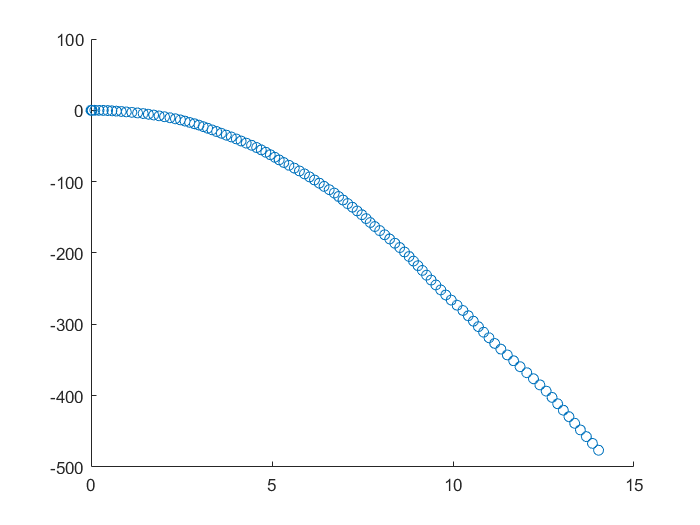

scatter(ax,ans.p_t.data(1,:),ans.p_t.data(2,:))

    กราฟที่ 2.2 ตำแหน่งของวัตถุที่ประมาณโดบใช้ Kalman filter

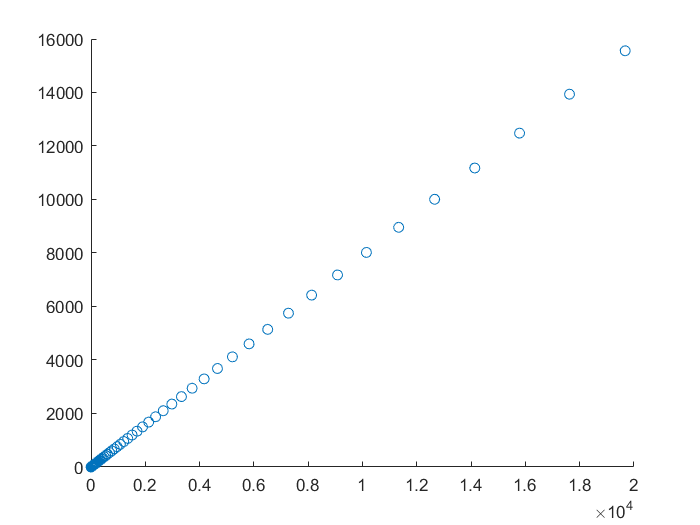

scatter(ax,ans.px_e.data,ans.py_e.data)

    จากกราฟที่ 2.1 และ 2.2 ทำให้เห็นว่าตำแหน่งของวัตถุที่เกิดขึ้นจริงกับตำแหน่งของวัตถุที่ประมาณจาก Kalman filter มีความใกล้เคียงกัน โดยมีความไม่แน่นอนของการประมาณตำแหน่งในส่วน state estimation โดยใช้ Kalman filter ดังนี้

% scatter()

**Discussion**